clear
clc


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


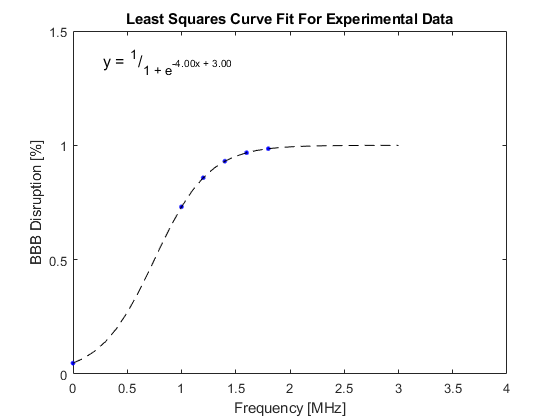

%%Load output data from data.mlx
%This data contains a matrix where the first row are x values for the curve
%And the second is Y values using the lsqcurvefit() function to generate
%constants for the experimental data fit
run('data.mlx')

load 'data.mat'

% Example 1: Finding 98% predicted BBB permeability
[x_98,y_98] = perm_val(data_out(1,:),data_out(2,:),.98);

fprintf('BBB Permeability is predicted to be %.3f%% at %.2f MHz',y_98,x_98)

BBB Permeability is predicted to be 0.985% at 1.80 MHz

%Example 2: Provide desired frequency to get output
f = 1.0; %[MHz]

f_in = freq_in(data_out(1,:),data_out(2,:),f);

fprintf('BBB Permeability is expected to be %.3f%% at %.2f MHz',f_in,f)

BBB Permeability is expected to be 0.731% at 1.00 MHz

%%Define global parameters to be used in calculations

global rho lambda mu y 

rho = .2; %day^-1
lambda = log(2)/7; %decay/day^-1
mu = 8; %mg^-1 day^-1
y = y_98;

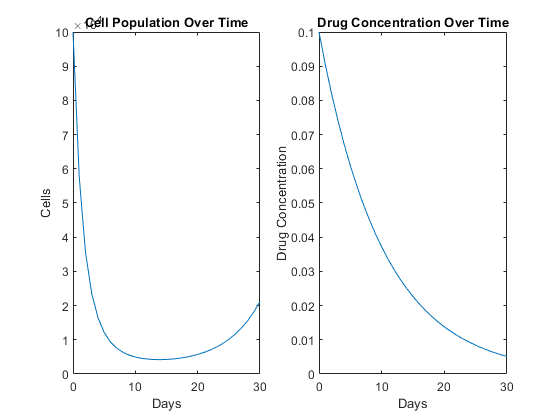

%%Example 1: Determine best value
%Run calculations
t = [0:1:30];
C0 = 10^5; %Cells
Ad = 0.1; %mg
ics = [C0, Ad];

[days,cells] = ode45(@cell_num,t,ics);

figure
subplot(1,2,1)
plot(days,cells(:,1))
xlabel('Days')
ylabel('Cells')
title('Cell Population Over Time')

subplot(1,2,2)
plot(days,cells(:,2))
xlabel('Days')
ylabel('Drug Concentration')
title('Drug Concentration Over Time')

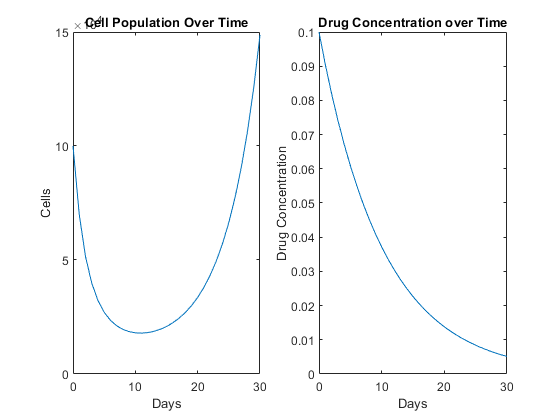

%%Example 2: Input Desired Frequency
y = f_in;
t = [0:1:30];
C0 = 10^5; %Cells
Ad = 0.1; %mg
ics = [C0, Ad];

[days,cells] = ode45(@cell_num,t,ics);

figure
subplot(1,2,1)
plot(days,cells(:,1))
xlabel('Days')
ylabel('Cells')
title('Cell Population Over Time')

subplot(1,2,2)
plot(days,cells(:,2))
xlabel('Days')
ylabel('Drug Concentration')
title('Drug Concentration over Time')